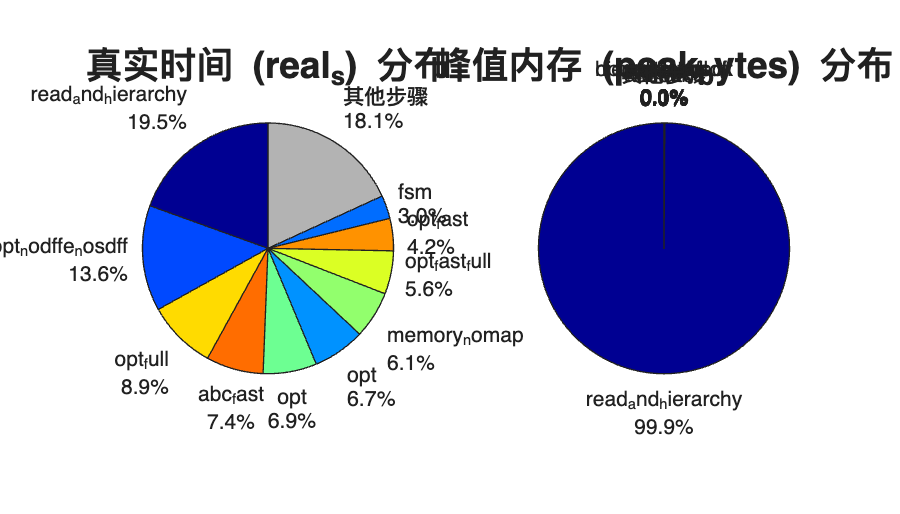

% 读取CSV文件
filename = 'profile.csv';
data = readtable(filename);

% 提取需要可视化的两列数据
targetColumns = {'real_s', 'peak_bytes'};
stepLabels = data.label;

% 创建图形窗口
figure('Position', [50, 50, 1400, 800]);

% 预定义颜色
colors = jet(height(data));

% 绘制第一个饼图：real_s
subplot(2, 2, [1, 3]); % 左侧大饼图

% 提取数据
real_s_data = data.real_s;
real_s_data(real_s_data <= 0) = eps;

% 计算百分比
real_s_percentages = 100 * real_s_data / sum(real_s_data);

% 只显示前10大值的标签，其他合并为"其他"
[sorted_vals, sorted_idx] = sort(real_s_data, 'descend');
if length(sorted_vals) > 10
    main_idx = sorted_idx(1:10);
    other_val = sum(real_s_data(sorted_idx(11:end)));
    plot_data = [real_s_data(main_idx); other_val];
    plot_labels = [stepLabels(main_idx); {'其他步骤'}];
    plot_percentages = [real_s_percentages(main_idx); 100*other_val/sum(real_s_data)];
else
    plot_data = real_s_data;
    plot_labels = stepLabels;
    plot_percentages = real_s_percentages;
end

% 绘制饼图
h1 = pie(plot_data);

% 设置颜色
color_idx = 1;
for j = 1:2:length(h1)
    if color_idx <= length(main_idx)
        set(h1(j), 'FaceColor', colors(main_idx(color_idx), :));
    else
        set(h1(j), 'FaceColor', [0.7, 0.7, 0.7]); % 灰色表示其他
    end
    color_idx = color_idx + 1;
end

% 添加百分比标签
for j = 2:2:length(h1)
    idx = j/2;
    h1(j).String = sprintf('%s\n%.1f%%', plot_labels{idx}, plot_percentages(idx));
    h1(j).FontSize = 8;
end

title('真实时间 (real_s) 分布', 'FontSize', 14, 'FontWeight', 'bold');

% 绘制第二个饼图：peak_bytes
subplot(2, 2, [2, 4]); % 右侧大饼图

% 提取数据
peak_bytes_data = data.peak_bytes;
peak_bytes_data(peak_bytes_data <= 0) = eps;

% 计算百分比
peak_bytes_percentages = 100 * peak_bytes_data / sum(peak_bytes_data);

% 只显示前10大值的标签
[sorted_vals, sorted_idx] = sort(peak_bytes_data, 'descend');
if length(sorted_vals) > 10
    main_idx = sorted_idx(1:10);
    other_val = sum(peak_bytes_data(sorted_idx(11:end)));
    plot_data = [peak_bytes_data(main_idx); other_val];
    plot_labels = [stepLabels(main_idx); {'其他步骤'}];
    plot_percentages = [peak_bytes_percentages(main_idx); 100*other_val/sum(peak_bytes_data)];
else
    plot_data = peak_bytes_data;
    plot_labels = stepLabels;
    plot_percentages = peak_bytes_percentages;
end

% 绘制饼图
h2 = pie(plot_data);

% 设置颜色
color_idx = 1;
for j = 1:2:length(h2)
    if color_idx <= length(main_idx)
        set(h2(j), 'FaceColor', colors(main_idx(color_idx), :));
    else
        set(h2(j), 'FaceColor', [0.7, 0.7, 0.7]); % 灰色表示其他
    end
    color_idx = color_idx + 1;
end

% 添加百分比标签
for j = 2:2:length(h2)
    idx = j/2;
    h2(j).String = sprintf('%s\n%.1f%%', plot_labels{idx}, plot_percentages(idx));
    h2(j).FontSize = 8;
end

title('峰值内存 (peak_bytes) 分布', 'FontSize', 14, 'FontWeight', 'bold');

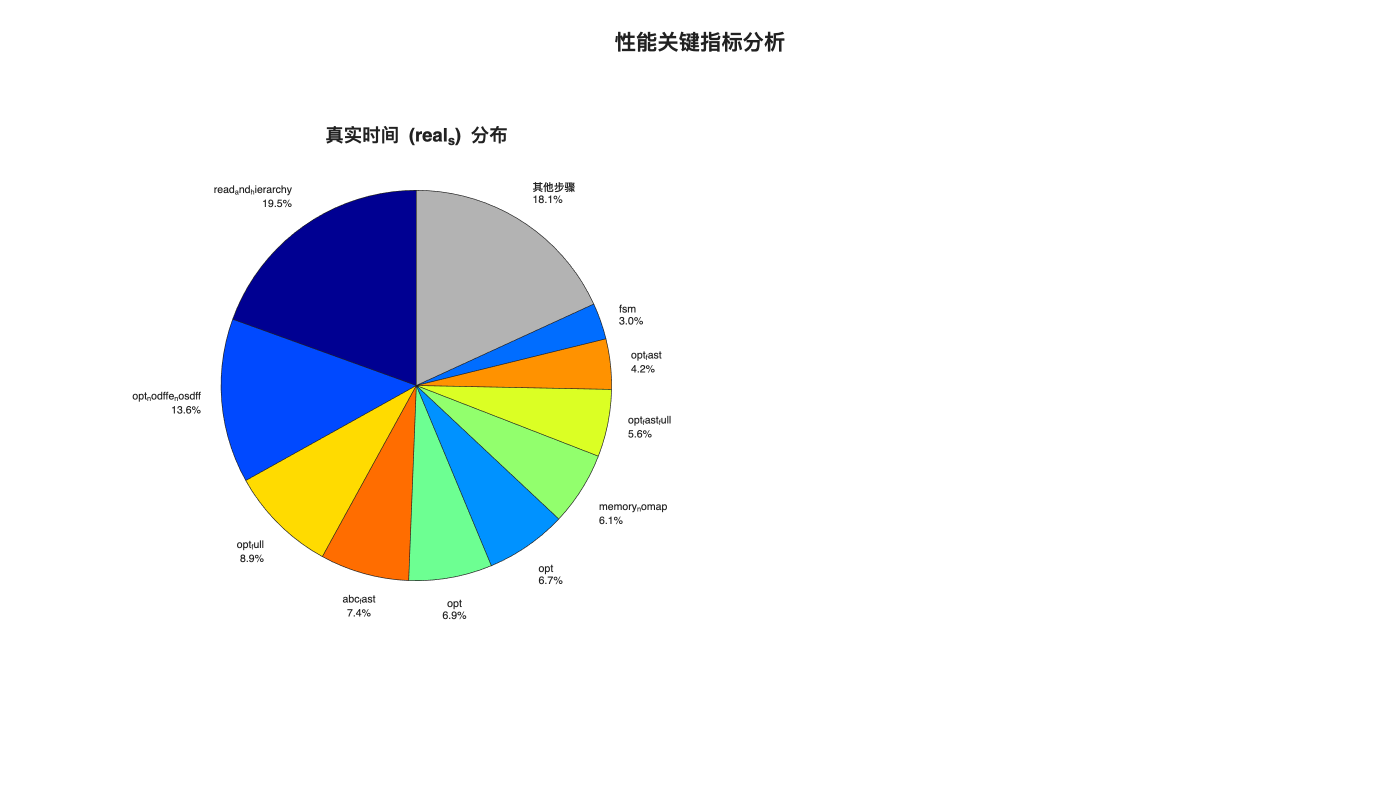


% 添加数据表格
subplot(2, 2, 4);
axis off;

% 准备表格数据
table_data = [data.real_s, data.peak_bytes];
table_data_formatted = cell(height(data), 2);
for i = 1:height(data)
    table_data_formatted{i, 1} = sprintf('%.2f s', data.real_s(i));
    table_data_formatted{i, 2} = sprintf('%.0f B', data.peak_bytes(i));
end

% 创建表格
uitable('Data', table_data_formatted, ...
        'ColumnName', {'real_s', 'peak_bytes'}, ...
        'RowName', stepLabels, ...
        'Position', [0.05, 0.05, 0.9, 0.9], ...
        'FontSize', 8);

% 添加总标题
sgtitle('性能关键指标分析', 'FontSize', 16, 'FontWeight', 'bold');


% 设置图形背景色
set(gcf, 'Color', 'white');